clear all
close all



## Roll angle

xlim = 60;
t_time = linspace(0,6,xlim+1);


## Q = 1 R = 1

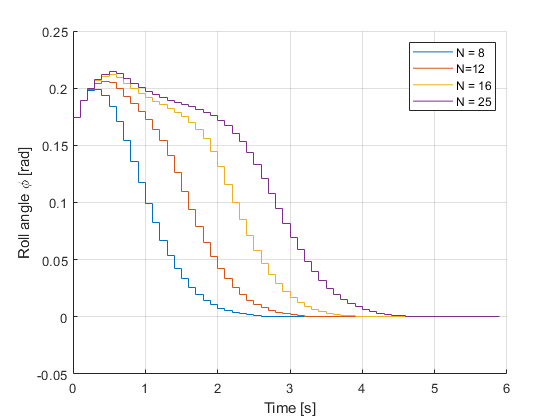

% load("MPC_reg_states_N\Q_100_R_1\MPC_reg_inputs_Q_100_R_1_N_8.mat")
load("MPC_states_Q_R_1\States_v_2_Q_1_R_1_N_8.mat")
x_N_8 = x;
% u_N_8 = u_store;

% load("MPC_reg_states_N\Q_100_R_1\MPC_reg_inputs_Q_100_R_1_N_12.mat")
load("MPC_states_Q_R_1\States_v_2_Q_1_R_1_N_16.mat")
x_N_16 = x;
% u_N_12 = u_store;

% load("MPC_reg_states_N\Q_100_R_1\MPC_reg_inputs_Q_100_R_1_N_12.mat")
load("MPC_states_Q_R_1\States_v_2_Q_1_R_1_N_12.mat")
x_N_12 = x;
% u_N_12 = u_store;


% load("MPC_reg_states_N\Q_100_R_1\MPC_reg_inputs_Q_100_R_1_N_16.mat")
load("MPC_states_Q_R_1\States_v_2_Q_1_R_1_N_25.mat")
x_N_25 = x;
% u_N_16 = u_store;

figure(1)
hold on
grid on
stairs(t_time(1:end-1),x_N_8(1,1:xlim))
stairs(t_time(1:end-1),x_N_12(1,1:xlim))
stairs(t_time(1:end-1),x_N_16(1,1:xlim))
stairs(t_time(1:end-1),x_N_25(1,1:xlim))
legend('N = 8','N=12','N = 16','N = 25')
ylabel('Roll angle \phi [rad]')
xlabel('Time [s]')
% title('State-feedback MPC regulator with v = 2 m/s, Q=1, R=1')
hold off

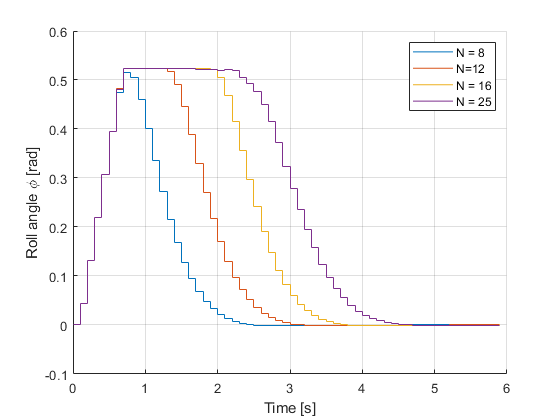


figure(2)
hold on
grid on
stairs(t_time(1:end-1),x_N_8(2,1:xlim))
stairs(t_time(1:end-1),x_N_12(2,1:xlim))
stairs(t_time(1:end-1),x_N_16(2,1:xlim))
stairs(t_time(1:end-1),x_N_25(2,1:xlim))
legend('N = 8','N=12','N = 16','N = 25')
ylabel('Roll angle \phi [rad]')
xlabel('Time [s]')
% title('State-feedback MPC regulator with v = 2 m/s, Q=1, R=1')
hold off

## Q = 100 R = 1



% load("MPC_reg_states_N\Q_100_R_1\MPC_reg_inputs_Q_100_R_1_N_8.mat")
% % load("MPC_reg_states_N\Q_100_R_1\MPC_reg_states_Q_100_R_1_N_8.mat")
% x_N_8 = u_store;
% % u_N_8 = u_store;
% 
% load("MPC_reg_states_N\Q_100_R_1\MPC_reg_inputs_Q_100_R_1_N_12.mat")
% % load("MPC_reg_states_N\Q_100_R_1\MPC_reg_states_Q_100_R_1_N_12.mat")
% x_N_12 = u_store;
% % u_N_12 = u_store;
% 
% load("MPC_reg_states_N\Q_100_R_1\MPC_reg_inputs_Q_100_R_1_N_16.mat")
% % load("MPC_reg_states_N\Q_100_R_1\MPC_reg_states_Q_100_R_1_N_16.mat")
% x_N_16 = u_store;
% % u_N_16 = u_store;
% 
% load("MPC_reg_states_N\Q_100_R_1\MPC_reg_inputs_Q_100_R_1_N_25.mat")
% % load("MPC_reg_states_N\Q_100_R_1\MPC_reg_states_Q_100_R_1_N_25.mat")
% x_N_25 = u_store;
% % u_N_25 = u_store;
% 
% 
% figure(1)
% hold on
% grid on
% stairs(t_time(1:end-1),x_N_8(1,1:xlim))
% stairs(t_time(1:end-1),x_N_12(1,1:xlim))
% stairs(t_time(1:end-1),x_N_16(1,1:xlim))
% stairs(t_time(1:end-1),x_N_25(1,1:xlim))
% legend('N = 8','N = 12','N = 16','N = 25')
% ylabel('Roll angle \phi [rad]')
% xlabel('Time [s]')
% title('Roll angle of state feedback MPC regulator Q=100, R=1')
% hold off


## Q = 100 R = 0.01

% % load("MPC_reg_states_N\Q_100_R_0_01\MPC_reg_inputs_N_8_Q_100_R_0_01.mat")
% % load("MPC_reg_states_N\Q_100_R_0_01\MPC_reg_states_N_8_Q_100_R_0_01.mat")
% % x_N_8 = x;
% % u_N_8 = u_store;
% 
% % load("MPC_reg_states_N\Q_100_R_0_01\MPC_reg_inputs_Q_100_R_0_01_N_12.mat")
% load("MPC_reg_states_N\Q_100_R_0_01\MPC_reg_states_Q_100_R_0_01_N_12.mat")
% x_N_12 = x;
% % u_N_12 = u_store;
% 
% % load("MPC_reg_states_N\Q_100_R_0_01\MPC_reg_inputs_Q_100_R_0_01_N_16.mat")
% load("MPC_reg_states_N\Q_100_R_0_01\MPC_reg_states_Q_100_R_0_01_N_16.mat")
% x_N_16 = x;
% % u_N_16 = u_store;
% 
% % load("MPC_reg_states_N\Q_100_R_0_01\MPC_reg_inputs_Q_100_R_0_01_N_25.mat")
% load("MPC_reg_states_N\Q_100_R_0_01\MPC_reg_states_Q_100_R_0_01_N_25.mat")
% x_N_25 = x;
% % u_N_25 = u_store;
% 
% 
% figure(2)
% hold on
% % stairs(x_N_8(1,1:xlim))
% stairs(t_time(1:end-1),x_N_12(1,1:xlim))
% stairs(t_time(1:end-1),x_N_16(1,1:xlim))
% stairs(t_time(1:end-1),x_N_25(1,1:xlim))
% legend('N = 12','N = 16','N = 25')
% ylabel('Roll angle \phi [rad]')
% xlabel('Time [s]')
% title('Roll angle of state feedback MPC regulator Q=100, R=0.01')
% hold off
% 

## Q = 1000 R = 0.01

% % load("MPC_reg_states_N\Q_100_R_0_01\MPC_reg_inputs_N_8_Q_100_R_0_01.mat")
% % load("MPC_reg_states_N\Q_100_R_0_01\MPC_reg_states_N_8_Q_100_R_0_01.mat")
% % x_N_8 = x;
% % u_N_8 = u_store;
% 
% % load("MPC_reg_states_N\Q_1000_R_0_01\MPC_reg_inputs_Q_1000_R_0_01_N_12.mat")
% load("MPC_reg_states_N\Q_1000_R_0_01\MPC_reg_states_Q_1000_R_0_01_N_12.mat")
% x_N_12 = x;
% % u_N_12 = u_store;
% 
% % load("MPC_reg_states_N\Q_1000_R_0_01\MPC_reg_inputs_Q_1000_R_0_01_N_16.mat")
% load("MPC_reg_states_N\Q_1000_R_0_01\MPC_reg_states_Q_1000_R_0_01_N_16.mat")
% x_N_16 = x;
% % u_N_16 = u_store;
% 
% % load("MPC_reg_states_N\Q_1000_R_0_01\MPC_reg_inputs_Q_1000_R_0_01_N_25.mat")
% load("MPC_reg_states_N\Q_1000_R_0_01\MPC_reg_states_Q_1000_R_0_01_N_25.mat")
% x_N_25 = x;
% % u_N_25 = u_store;
% 
% 
% figure(3)
% hold on
% % stairs(x_N_8(1,1:xlim))
% stairs(t_time(1:end-1),x_N_12(1,1:xlim))
% stairs(t_time(1:end-1),x_N_16(1,1:xlim))
% stairs(t_time(1:end-1),x_N_25(1,1:xlim))
% legend('N = 12','N = 16','N = 25')
% ylabel('Roll angle \phi [rad]')
% xlabel('Time [s]')
% title('Roll angle of state feedback MPC regulator Q=1000, R=0.01')
% hold off


## Steering angle

xlim = 60;
t_time = linspace(0,6,xlim+1);


## Q = 100 R = 1

% 
% 
% % load("MPC_reg_states_N\Q_100_R_1\MPC_reg_inputs_Q_100_R_1_N_8.mat")
% load("MPC_reg_states_N\Q_100_R_1\MPC_reg_states_Q_100_R_1_N_8.mat")
% x_N_8 = x;
% % u_N_8 = u_store;
% 
% % load("MPC_reg_states_N\Q_100_R_1\MPC_reg_inputs_Q_100_R_1_N_12.mat")
% load("MPC_reg_states_N\Q_100_R_1\MPC_reg_states_Q_100_R_1_N_12.mat")
% x_N_12 = x;
% % u_N_12 = u_store;
% 
% % load("MPC_reg_states_N\Q_100_R_1\MPC_reg_inputs_Q_100_R_1_N_16.mat")
% load("MPC_reg_states_N\Q_100_R_1\MPC_reg_states_Q_100_R_1_N_16.mat")
% x_N_16 = x;
% % u_N_16 = u_store;
% 
% % load("MPC_reg_states_N\Q_100_R_1\MPC_reg_inputs_Q_100_R_1_N_25.mat")
% load("MPC_reg_states_N\Q_100_R_1\MPC_reg_states_Q_100_R_1_N_25.mat")
% x_N_25 = x;
% % u_N_25 = u_store;
% 
% 
% figure(4)
% hold on
% stairs(t_time(1:end-1),x_N_8(2,1:xlim))
% stairs(t_time(1:end-1),x_N_12(2,1:xlim))
% stairs(t_time(1:end-1),x_N_16(2,1:xlim))
% stairs(t_time(1:end-1),x_N_25(2,1:xlim))
% legend('N = 8','N = 12','N = 16','N = 25')
% ylabel('Steering angle \delta [rad]')
% xlabel('Time [s]')
% title('Steering angle of state feedback MPC regulator Q=100, R=1')
% hold off


## Q = 100 R = 0.01

% % load("MPC_reg_states_N\Q_100_R_0_01\MPC_reg_inputs_N_8_Q_100_R_0_01.mat")
% % load("MPC_reg_states_N\Q_100_R_0_01\MPC_reg_states_N_8_Q_100_R_0_01.mat")
% % x_N_8 = x;
% % u_N_8 = u_store;
% 
% % load("MPC_reg_states_N\Q_100_R_0_01\MPC_reg_inputs_Q_100_R_0_01_N_12.mat")
% load("MPC_reg_states_N\Q_100_R_0_01\MPC_reg_states_Q_100_R_0_01_N_12.mat")
% x_N_12 = x;
% % u_N_12 = u_store;
% 
% % load("MPC_reg_states_N\Q_100_R_0_01\MPC_reg_inputs_Q_100_R_0_01_N_16.mat")
% load("MPC_reg_states_N\Q_100_R_0_01\MPC_reg_states_Q_100_R_0_01_N_16.mat")
% x_N_16 = x;
% % u_N_16 = u_store;
% 
% % load("MPC_reg_states_N\Q_100_R_0_01\MPC_reg_inputs_Q_100_R_0_01_N_25.mat")
% load("MPC_reg_states_N\Q_100_R_0_01\MPC_reg_states_Q_100_R_0_01_N_25.mat")
% x_N_25 = x;
% % u_N_25 = u_store;
% 
% 
% figure(5)
% hold on
% % stairs(t_time(1:end-1),x_N_8(2,1:xlim))
% stairs(t_time(1:end-1),x_N_12(2,1:xlim))
% stairs(t_time(1:end-1),x_N_16(2,1:xlim))
% stairs(t_time(1:end-1),x_N_25(2,1:xlim))
% legend('N = 12','N = 16','N = 25')
% ylabel('Steering angle \delta [rad]')
% xlabel('Time [s]')
% title('Steering angle of state feedback MPC regulator Q=100, R=0.01')
% hold off
% 

## Q = 1000 R = 0.01

% % load("MPC_reg_states_N\Q_100_R_0_01\MPC_reg_inputs_N_8_Q_100_R_0_01.mat")
% % load("MPC_reg_states_N\Q_100_R_0_01\MPC_reg_states_N_8_Q_100_R_0_01.mat")
% % x_N_8 = x;
% % u_N_8 = u_store;
% 
% % load("MPC_reg_states_N\Q_1000_R_0_01\MPC_reg_inputs_Q_1000_R_0_01_N_12.mat")
% load("MPC_reg_states_N\Q_1000_R_0_01\MPC_reg_states_Q_1000_R_0_01_N_12.mat")
% x_N_12 = x;
% % u_N_12 = u_store;
% 
% % load("MPC_reg_states_N\Q_1000_R_0_01\MPC_reg_inputs_Q_1000_R_0_01_N_16.mat")
% load("MPC_reg_states_N\Q_1000_R_0_01\MPC_reg_states_Q_1000_R_0_01_N_16.mat")
% x_N_16 = x;
% % u_N_16 = u_store;
% 
% % load("MPC_reg_states_N\Q_1000_R_0_01\MPC_reg_inputs_Q_1000_R_0_01_N_25.mat")
% load("MPC_reg_states_N\Q_1000_R_0_01\MPC_reg_states_Q_1000_R_0_01_N_25.mat")
% x_N_25 = x;
% % u_N_25 = u_store;
% 
% 
% figure(6)
% hold on
% % stairs(t_time(1:end-1),x_N_8(2,1:xlim))
% stairs(t_time(1:end-1),x_N_12(2,1:xlim))
% stairs(t_time(1:end-1),x_N_16(2,1:xlim))
% stairs(t_time(1:end-1),x_N_25(2,1:xlim))
% legend('N = 12','N = 16','N = 25')
% ylabel('Steering angle \delta [rad]')
% xlabel('Time [s]')
% title('Steering angle of state feedback MPC regulator Q=1000, R=0.01')
% hold off
